# Aero 557 : Homework 2

#### Isaac Velasco

clc;clear;close all
addpath('..\Functions\')

### Problem 1: Editing Data with Linear Least Squares

Students collect marble data and are wondering if they should remove any of the data to get a  better fit.  There are 10 student collected samples are $x_{o_i} = \left[\matrix{1 & 2&3&4&5&6&7&8&9&10}\right]$ and $y_{o_i} = \left[\matrix{1&2&2&3&4&4&5&7&9 &9}\right]$. Assume the mathematical model is $y = \alpha + \beta\cdot x$. Find the best estimate of the state.  Determine what detecting and eliminating a bad data point would do to the state.  What happens to the errors and confidence values if you remove a bad data point? 

xo       = [1:10]';
yo       = [1;2;2;3;4;4;5;7;9;9];
[xhat,P] = llsqrs(xo,yo);
r        = residuals(xo,yo,xhat);
RMSo     = rms(r);

[fxo,fyo,fpts] = llsfilter(xo,yo,r,0.5);
[fxhat,fP] = llsqrs(fxo,fyo);
fr         = residuals(fxo,fyo,fxhat);
RMSf       = rms(fr);
perdif     = [abs(abs(r(1:5)) - abs(fr(1:5)))./abs(r(1:5));nan;...
              abs(abs(r(7:8)) - abs(fr(6:7)))./abs(r(7:8));nan;...
              abs(abs(r(10)) - abs(fr(8)))./abs(r(10))];

fr      = [fr(1:5);nan;fr(7:8);nan;fr(8)];
col_n   = {'Orignial ϵ','Filtered ϵ','Percent Diff'};
row_n   = {'Data 1','Data 2','Data 3','Data 4','Data 5',...
           'Data 6','Data 7','Data 8','Data 9','Data 10'};
err_tbl = table(r,fr,perdif,'VariableNames',col_n,'RowNames',row_n);
disp(err_tbl)

               Orignial ϵ    Filtered ϵ    Percent Diff
               __________    __________    ____________

    Data 1       0.54545       0.34559       0.36642   
    Data 2       0.62424       0.47794       0.23437   
    Data 3      -0.29697      -0.38971       0.31227   
    Data 4      -0.21818      -0.25735       0.17953   
    Data 5      -0.13939        -0.125       0.10326   
    Data 6       -1.0606           NaN           NaN   
    Data 7      -0.98182       0.27206       0.12377   
    Data 8       0.09697       0.53676        1.8056   
    Data 9        1.1758           NaN           NaN   
    Data 10      0.25455       0.53676        1.1087   




col_n = {'Equation','Confidence α','Confidence β','RMS'};
row_n = {'Original','Filtered'};
yc    = [sprintf(['y = %.4f + %.4f*x'],xhat(1),xhat(2));sprintf(['y = %.4f + %.4f*x'],fxhat(1),fxhat(2))];
confa = [sprintf(['%.4f ± %.4f'],xhat(1),sqrt(P(1,1)));sprintf(['%.4f ± %.4f'],fxhat(1),sqrt(fP(1,1)))];
confb = [sprintf(['%.4f ± %.4f'],xhat(2),sqrt(P(2,2)));sprintf(['%.4f ± %.4f'],fxhat(2),sqrt(fP(2,2)))];
RMS   = [RMSo;RMSf];
llsspec = table(yc,confa,confb,RMS,'VariableNames',col_n,'RowNames',row_n);
disp(llsspec)

                       Equation             Confidence α       Confidence β        RMS  
                ______________________    ________________    _______________    _______

    Original    y = -0.4667 + 0.9212*x    -0.4667 ± 0.6831    0.9212 ± 0.1101    0.66241
    Filtered    y = -0.2132 + 0.8676*x    -0.2132 ± 0.7019    0.8676 ± 0.1213    0.45878



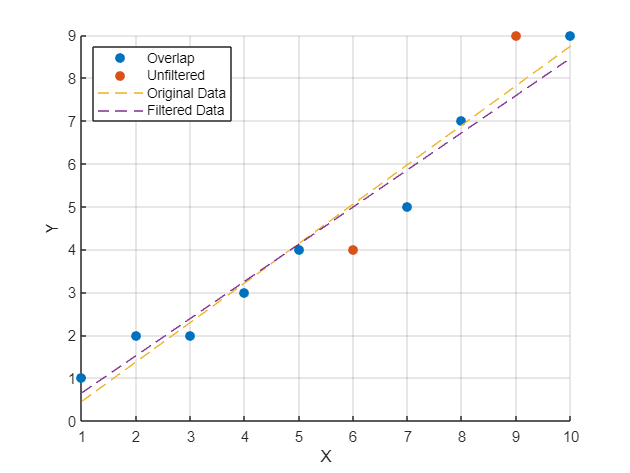


figure
scatter(fxo,fyo,'MarkerFaceColor','#0072BD')
hold on
grid on
scatter(xo(fpts),yo(fpts),'MarkerFaceColor','#D95319')
plot(xo,xhat(1)+xhat(2).*xo,'--')
plot(fxo,fxhat(1)+fxhat(2).*fxo,'--')
xlabel('X')
ylabel('Y')
legend('Overlap','Unfiltered','Original Data','Filtered Data','Location','northwest')
hold off

### Problem 2: Weighted Least-Squares

Using the data taken from the text file posted for problem 2 (UT date, UT time, range, Az (deg), El (deg)) taken at a site at latitude ($21.5748^\circ$), longitude ($-158.2706^\circ$) and altitude ($300.2$ m) with a range error $92.5$ m, azimuth error = $0.0224^\circ$, and elevation error = $0.0139^\circ$, determine the state vector and co-variance matrix at the first observation as an epoch.

% get data
latitude  = 21.5748; % deg
longitude = -158.2706; % deg
altitude  = 300.2/1000; % km
err       = table(92.5/1000,0.0224,0.0139,'VariableNames',{'rho','Az','el'});
data      = readtable('Data4Problem2Hw2test2.txt');
data.Properties.VariableNames = {'yyyy','mm','dd','H','M','S','Az','el','rho'};

% acquire nominal state vector
[Xk,Pk,Hk,Wk,yk,bXk,rk] = NLWLS(data,err,latitude,longitude,altitude,'hg');
fmt = ['Nominal state: [', repmat('%g, ', 1, numel(Xk)-1), '%g] (km,km/s)\n'];
fprintf(fmt,Xk)

Nominal state: [5753.12, 2672.96, 3440.63, 4.32896, -1.9244, -5.74686] (km,km/s)



% retireve eigen values from variance/covariance matrix
r_evals    = eig(Pk(1:3,1:3));
v_evals    = eig(Pk(4:6,4:6));
Pmatk      = diag([r_evals(1) r_evals(2) r_evals(3) v_evals(1) v_evals(2) v_evals(3)]);
Ptable     = table(Pmatk(:,1),Pmatk(:,2),Pmatk(:,3),Pmatk(:,4),Pmatk(:,5),Pmatk(:,6));
Ptable.Properties.VariableNames = {'σx','σy','σz','σxdot','σydot','σzdot'};
disp('Eigen values for P matrix:')

Eigen values for P matrix:


disp(Ptable)

      σx      σy       σz        σxdot        σydot         σzdot   
    ______    ___    ______    _________    __________    __________

    30.567      0         0            0             0             0
         0    105         0            0             0             0
         0      0    192.27            0             0             0
         0      0         0    0.0043149             0             0
         0      0         0            0    0.00020712             0
         0      0         0            0             0    9.2541e-06



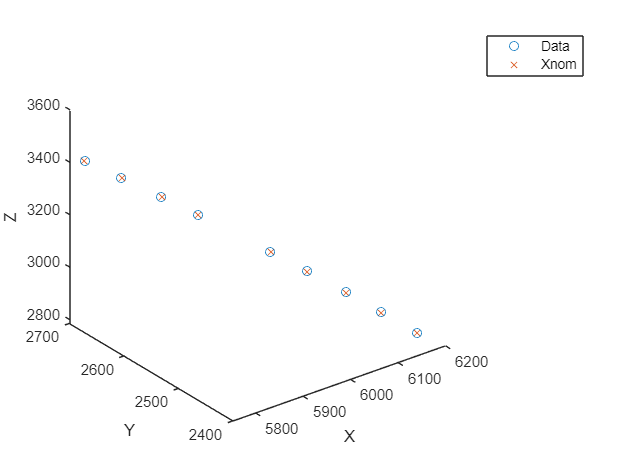


% propagate nominal state and compare to data state at each time interval
rXk = zeros(9,3);
rXk(1,:) = Xk(1:3);
dates = [data.yyyy data.mm data.dd data.H data.M data.S];
options = odeset('RelTol',1e-8,'AbsTol',1e-8);
for obs = 2:9
    [~,sv] = ode45(@orbitprop,[0  etime(dates(obs,:),dates(1,:))],Xk,options,398600);
    rXk(obs,:) = sv(end,1:3);
end

figure
plot3(rk(:,1),rk(:,2),rk(:,3),'o',rXk(:,1),rXk(:,2),rXk(:,3),'x')
xlabel('X')
ylabel('Y')
zlabel('Z')
legend('Data','Xnom')

### Problem 3: Sequential Batch Filter

After you finish running the data for problem 2, the site sends you more observations (see problem 3 text file).  The data was taken from the same site with the same noise values.  Find the new state and *P matrix*.  How much did it change? 

% repeat problem no 2 for new data
newdata   = readtable('DataforP3H2test.txt');
newdata.Properties.VariableNames = {'yyyy','mm','dd','H','M','S','Az','el','rho'};
[Xn,Pn,Hn,Wn,yn,bXn,rn] = NLWLS(newdata,err,latitude,longitude,altitude,'hg');

% apply new data to old data
Wk      = Wk/norm(Wk);
Wn      = Wn/norm(Wn);
Xhat   = (inv(Pk) + inv(Pn))\(Hk'*Wk*yk + Hn'*Wn*yn);
Xnomnew = Xk + Xhat';
Pnew    = Pk + Pn;

% display differences
fmt = ['Previous state: [', repmat('%g, ', 1, numel(Xnomnew)-1), '%g] (km,km/s)\n'];
fprintf(fmt,Xk)
fmt = ['New state: [', repmat('%g, ', 1, numel(Xnomnew)-1), '%g] (km,km/s)\n'];
fprintf(fmt, Xnomnew);
disp('Previous P matrix:')
disp(Pk)
disp('New P matrix:')
disp(Pnew)

% retireve eigen values from variance/covariance matrix
r_evals    = eig(Pnew(1:3,1:3));
v_evals    = eig(Pnew(4:6,4:6));
Pmat       = diag([r_evals(1) r_evals(2) r_evals(3) v_evals(1) v_evals(2) v_evals(3)]);
Ptable     = table(Pmat(:,1),Pmat(:,2),Pmat(:,3),Pmat(:,4),Pmat(:,5),Pmat(:,6));
Ptable.Properties.VariableNames = {'σx','σy','σz','σxdot','σydot','σzdot'};
disp('Eigen values for P matrix:')
disp(Ptable)

% propagate new nominal state and compare to whole data state at each time interval
rXc = zeros(17,3);
rXc(1,:) = Xnomnew(1:3);
dates = [data.yyyy data.mm data.dd data.H data.M data.S;...
        newdata.yyyy newdata.mm newdata.dd newdata.H newdata.M newdata.S];
options = odeset('RelTol',1e-8,'AbsTol',1e-8);
for obs = 2:17
    [~,sv] = ode45(@orbitprop,[0  etime(dates(obs,:),dates(1,:))],Xnomnew,options,398600);
    rXc(obs,:) = sv(end,1:3);
end

figure
plot3(rk(:,1),rk(:,2),rk(:,3),'ob',rn(:,1),rn(:,2),rn(:,3),'ob',rXc(:,1),rXc(:,2),rXc(:,3),'xr')
xlabel('X')
ylabel('Y')
zlabel('Z')
legend('Data','','Xnomnew')